# Animation

# EXAMPLE 6

The goal of this example is to draw the square in its original size, then cause it to disappear, and fi�nally to redraw it as it looks after it is dilated by a factor of 9/8. If this operation is repeated ten times in succession, the square will appear to be expanding.

To do this we need to �first plot the square and store its handle in `p`:

After we transform the matrix by multiplying by the appropriate transformation matrix, we can erase the original �gure and draw the new �gure with the command

Since we are repeating the same operation ten times, we will use a for loop. After we have gone through this loop, we create another one that contracts the matrix by a factor of 8/9, thereby returning it to its original size.

The following are the commands that produce the eff�ects.  The pause(0.2) command is used to adjust the speed of the plots so that we can see the graphs before they are erased. You might need to change the 0.2 to suit the speed of your machine.

Run the commands to see the animation.

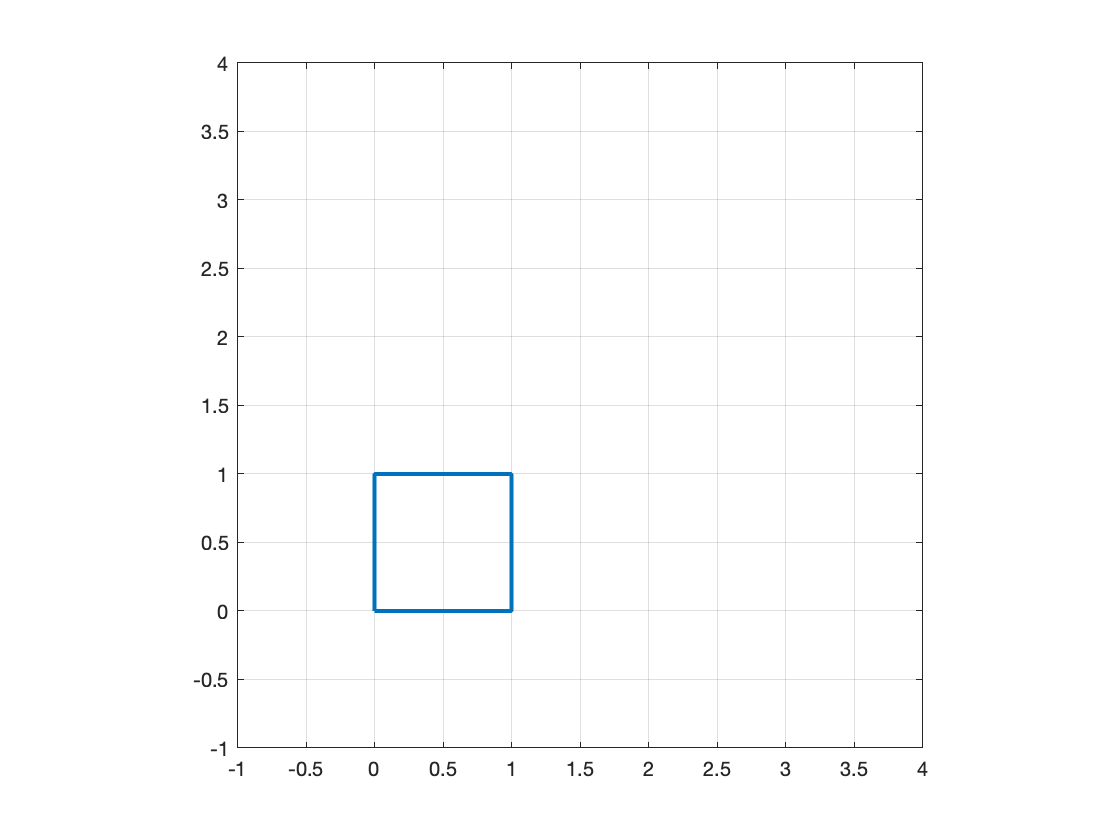

clf % clear all settings for the plot
S=[0 ,1 ,1 ,0 ,0;0 ,0 ,1 ,1 ,0];
D1 = 9/8*eye(2); % dilation matrix
p = plot(S(1,:),S(2,:),'linewidth',2); % plot the square
axis([-1,4,-1,4]) % set size of the graph
axis square , grid on % make the display square
hold on % hold the current graph
for i = 1:10
   S = D1*S; % dilate the square
   set(p,'xdata',S(1 ,:),'ydata',S(2,:)); % erase original figure 
                         % and plot the transformed figure
   pause(0.2) % adjust this pause rate to suit your computer .
end
D2 = 8/9*eye(2); % contraction matrix
for i = 1:10
   S = D2*S; % contract the square
   set(p,'xdata',S(1 ,:),'ydata',S(2,:)); % erase original figure 
                          % and plot the transformed figure
   pause(0.2) % adjust this pause rate to suit your computer .
end
hold off